clear

experiment_names = ["AQ_SST0-27" "AQ_SST7-27" "AQ_SST15-27" "AQ_SST20-27" "AQ_SST_MarineHeatwave" "AQ_2xCO2" "ERA5"];
experiment_names2 = ["SST0-27" "SST7-27" "SST15-27" "SST20-27" "SST MH" "2xCO2" "ERA5"];
num_experiments = length(experiment_names);
ds_names = ["_Rows_Cols_Matrix.csv", "_average_lons.csv", "_adjusted_lons.csv", "_average_lats.csv", "_durations.csv", "_start_tsteps.csv"];
all_exp_ds_cell = cell(length(ds_names),num_experiments);
for i = 1:size(all_exp_ds_cell,1)
    for j = 1:size(all_exp_ds_cell,2)
        if ds_names(i) == "_adjusted_lons.csv"
            tmp_ds_nm = experiment_names(j) + "/" + experiment_names(j) + "_average_lons.csv";
            tmp_lons = readmatrix(tmp_ds_nm);
            all_exp_ds_cell{i,j} = cat(1,tmp_lons,tmp_lons(tmp_lons<10)+350,tmp_lons(tmp_lons>350)-350);
        else
            tmp_ds_nm = experiment_names(j) + "/" + experiment_names(j) + ds_names(i);
            all_exp_ds_cell{i,j} =  readmatrix(tmp_ds_nm);
        end
    end
end
% The rows = [rcm lon adj_lon lat dur tstep] and cols = ["SST0-27" "SST7-27" "SST15-27" "SST20-27" "SST MH" "2xCO2"]
all_exp_ds_cell

all_exp_ds_cell = 6×7 cell array
    {  164×42460 double}    {  168×50616 double}    {  272×55130 double}    {  210×83636 double}    {  205×44336 double}    {  168×42408 double}    {  240×48000 double}
    {21230×1     double}    {25308×1     double}    {27565×1     double}    {41818×1     double}    {22168×1     double}    {21204×1     double}    {24000×1     double}
    {21803×1     double}    {25997×1     double}    {28403×1     double}    {43068×1     double}    {22712×1     double}    {21779×1     double}    {24393×1     double}
    {21230×1     double}    {25308×1     double}    {27565×1     double}    {41818×1     double}    {22168×1     double}    {21204×1     double}    {24000×1     double}
    {21230×1     double}    {25308×1     double}    {27565×1     double}    {41818×1     double}    {22168×1     double}    {21204×1     double}    {24000×1     double}
    {21230×1     double}    {25308×1     double}    {27565×1     double}    {41818×1     double}    {22168×1     double}  


% Fitting kernel distributions to the data
stat_cell = cell(4,num_experiments);
num_points = 1000;
xs = {linspace(0,360,num_points);linspace(0,360,num_points);linspace(0,90,num_points);linspace(0,21*4,num_points)};
xs = repmat(xs,[1 num_experiments]);
for i = 1:size(stat_cell,1)
    for j = 1:size(stat_cell,2)
        x = xs{i,j};
        data = all_exp_ds_cell{i+1,j};
        [pd, pd_pdf, pd_cdf, x] = stat_eval(data,x);
        stat_cell{i,j} = {pd,pd_pdf,pd_cdf,x};
    end
end
% the rows = [lon adj_lon lat dur ts] and cols = experiment_name
% inside the cell, it's {prob_dist pdf cdf xs}
stat_cell

stat_cell = 4×7 cell array
    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}
    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}
    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}
    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×4 cell}


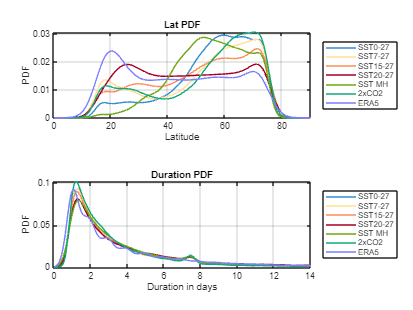


% % Initial Lat, Lon, and Duration breakdowns
figure;
t0 = tiledlayout(2,1);
cbf_div_cmap = [
52, 141, 209;
254,224,144;
252,141,89;
165,0,38;
108, 168, 17;
17, 168, 120;
125 125 255]/255;
cmap1 = cbf_div_cmap;
% cmap_length = size(cmap1,1);
% cmap_vec = floor(linspace(1,cmap_length,num_experiments));

nexttile(1);
tmp_stat = stat_cell{3,1};
tmp_dur_pdf = tmp_stat{2};
tmp_dur_xs = tmp_stat{4};
plot(tmp_dur_xs,tmp_dur_pdf,'Color',cmap1(1,:));
hold on
for i = 2:num_experiments
    tmp_stat = stat_cell{3,i};
    tmp_dur_pdf = tmp_stat{2};
    tmp_dur_xs = tmp_stat{4};
    plot(tmp_dur_xs,tmp_dur_pdf,'Color',cmap1(i,:));
end
hold off
grid on
pbaspect([3 1 1])
xlabel("Latitude")
ylabel("PDF")
xlim([0 90])
title("Lat PDF")
legend(experiment_names2,'Location','eastoutside')

nexttile(2);
tmp_stat = stat_cell{4,1};
tmp_dur_pdf = tmp_stat{2};
tmp_dur_xs = tmp_stat{4};
plot(tmp_dur_xs/4,tmp_dur_pdf,'Color',cmap1(1,:));
hold on
for i = 2:num_experiments
    tmp_stat = stat_cell{4,i};
    tmp_dur_pdf = tmp_stat{2};
    tmp_dur_xs = tmp_stat{4};
    plot(tmp_dur_xs/4,tmp_dur_pdf,'Color',cmap1(i,:));
end
hold off
grid on
pbaspect([3 1 1])
xlabel("Duration in days")
ylabel("PDF")
xlim([0 14])
title("Duration PDF")
legend(experiment_names2,'Location','eastoutside')

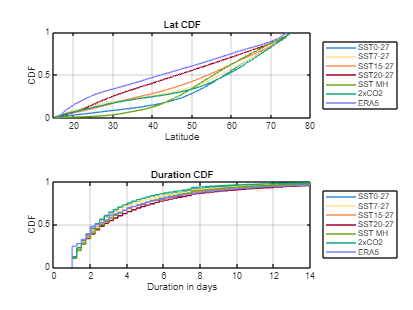

% saveas(t0,"AQ_Analysis_Figures/"+"Lat_Dur_pdf.png")

figure;
t1 = tiledlayout(2,1);

nexttile(1);
[h(1), lat_stats(1)] = cdfplot(all_exp_ds_cell{4,1});
h(1).Color = cmap1(1,:);
hold on
for i = 2:num_experiments
    [h(i), ~] = cdfplot(all_exp_ds_cell{4,i});
    h(i).Color = cmap1(i,:);
end
hold off
pbaspect([3 1 1])
xlabel("Latitude")
ylabel("CDF")
xlim([15 80])
title("Lat CDF")
legend(experiment_names2,'Location','eastoutside')

nexttile(2);
[h(1), lon_stats(i)] = cdfplot(all_exp_ds_cell{5,1}/4);
h(1).Color = cmap1(1,:);
hold on
for i = 2:num_experiments
    [h(i), ~] = cdfplot(all_exp_ds_cell{5,i}/4);
    h(i).Color = cmap1(i,:);
end
hold off
pbaspect([3 1 1])
xlabel("Duration in days")
ylabel("CDF")
xlim([0 14])
title("Duration CDF")
legend(experiment_names2,'Location','eastoutside')

% saveas(t1,"AQ_Analysis_Figures/"+"Lat_Dur_cdf.png")

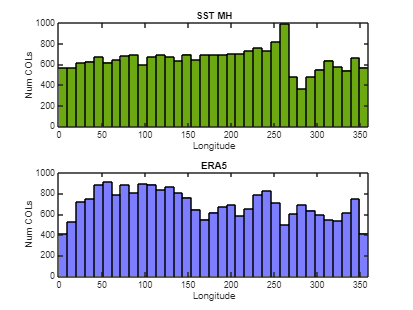


figure;
t2 = tiledlayout('flow');
nbins = 36;
bin_edges = linspace(0,360,nbins);
for i = [5 7]
    nexttile(i);
    histogram(all_exp_ds_cell{3,i},nbins,"BinEdges",bin_edges,'FaceColor',cmap1(i,:),'FaceAlpha',1);
    pbaspect([3 1 1])
    xlabel("Longitude")
    ylabel("Num COLs")
    xlim([0 360])
    % ylim([0 1400])
    title(experiment_names2(i))
end

% saveas(t2,"AQ_Analysis_Figures/"+"Lon_hist.png")

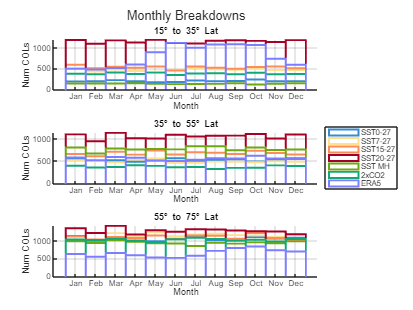

% % Breakdown season and Lat
t_season = tiledlayout(3,1);

datetime_vec = datetime(2000,1,1,6,0,0):.25:datetime(2050,1,1,6,0,0);
for i = 1:7
    tmp_ds = all_exp_ds_cell{6,i};
    tmp_lats = all_exp_ds_cell{4,i};
    tmp_ds = tmp_ds(tmp_lats<=35);
    tmp_datetimes = datetime_vec(tmp_ds);
    tmp_months = month(datetime(tmp_datetimes));

    nexttile(1);
    hold on
    histogram(tmp_months,'EdgeColor',cmap1(i,:),'EdgeAlpha',1,'FaceAlpha',0,'LineWidth',2)

end
hold off
grid on
month_names = {'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'};
xlabel("Month")
xticks(1:1:12)
xticklabels(month_names)
ylabel("Num COLs")
% legend(experiment_names2,Location="eastoutside")
title("15\circ to 35\circ Lat")

for i = 1:7
    tmp_ds = all_exp_ds_cell{6,i};
    tmp_lats = all_exp_ds_cell{4,i};
    tmp_ds = tmp_ds(tmp_lats>=35&tmp_lats<=55);
    tmp_datetimes = datetime_vec(tmp_ds);
    tmp_months = month(datetime(tmp_datetimes));


    nexttile(2);
    hold on
    histogram(tmp_months,'EdgeColor',cmap1(i,:),'EdgeAlpha',1,'FaceAlpha',0,'LineWidth',2)

end
hold off
grid on
month_names = {'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'};
xlabel("Month")
xticks(1:1:12)
xticklabels(month_names)
ylabel("Num COLs")
legend(experiment_names2,Location="eastoutside")
title("35\circ to 55\circ Lat")

for i = 1:7
    tmp_ds = all_exp_ds_cell{6,i};
    tmp_lats = all_exp_ds_cell{4,i};
    tmp_ds = tmp_ds(tmp_lats>=55);
    tmp_datetimes = datetime_vec(tmp_ds);
    tmp_months = month(datetime(tmp_datetimes));

    nexttile(3);
    hold on
    histogram(tmp_months,'EdgeColor',cmap1(i,:),'EdgeAlpha',1,'FaceAlpha',0,'LineWidth',2)

end
hold off
grid on
month_names = {'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'};
xlabel("Month")
xticks(1:1:12)
xticklabels(month_names)
ylabel("Num COLs")
title("55\circ to 75\circ Lat")

title(t_season,"Monthly Breakdowns")

% saveas(t_season,"AQ_Analysis_Figures/"+"COL_by_month_and_lat.png")

% % Breakdown Lat and Lon
t_latlon = tiledlayout(3,1);

for i = 7
    tmp_ds = all_exp_ds_cell{2,i};
    tmp_lats = all_exp_ds_cell{4,i};
    tmp_ds = tmp_ds(tmp_lats<=35);
    tmp_ds = cat(1,tmp_ds,tmp_ds(tmp_ds<10)+350,tmp_ds(tmp_ds>350)-350);

    nexttile(1);
    hold on
    histogram(tmp_ds,nbins,"BinEdges",bin_edges,'EdgeColor',cmap1(i,:),'EdgeAlpha',1,'FaceAlpha',0,'LineWidth',2)

end
hold off
grid on
pbaspect([3 1 1])
xlabel("Longitude")
ylabel("Num COLs")
xlim([0 360])
title("15\circ to 35\circ Lat")

for i = 7
    tmp_ds = all_exp_ds_cell{2,i};
    tmp_lats = all_exp_ds_cell{4,i};
    tmp_ds = tmp_ds(tmp_lats>=35&tmp_lats<=55);
    tmp_ds = cat(1,tmp_ds,tmp_ds(tmp_ds<10)+350,tmp_ds(tmp_ds>350)-350);

    nexttile(2);
    hold on
    histogram(tmp_ds,nbins,"BinEdges",bin_edges,'EdgeColor',cmap1(i,:),'EdgeAlpha',1,'FaceAlpha',0,'LineWidth',2)

end
hold off
grid on
pbaspect([3 1 1])
xlabel("Longitude")
ylabel("Num COLs")
xlim([0 360])
legend(experiment_names2(:),Location="eastoutside")

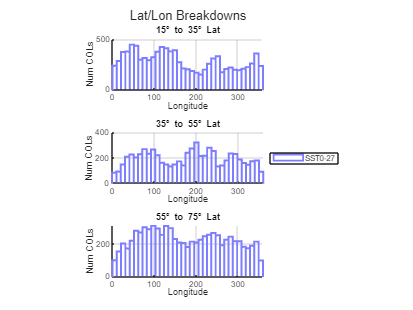

title("35\circ to 55\circ Lat")

for i = 7
    tmp_ds = all_exp_ds_cell{2,i};
    tmp_lats = all_exp_ds_cell{4,i};
    tmp_ds = tmp_ds(tmp_lats>=55);
    tmp_ds = cat(1,tmp_ds,tmp_ds(tmp_ds<10)+350,tmp_ds(tmp_ds>350)-350);

    nexttile(3);
    hold on
    histogram(tmp_ds,nbins,"BinEdges",bin_edges,'EdgeColor',cmap1(i,:),'EdgeAlpha',1,'FaceAlpha',0,'LineWidth',2)

end
hold off
grid on
pbaspect([3 1 1])
xlabel("Longitude")
ylabel("Num COLs")
xlim([0 360])
title("55\circ to 75\circ Lat")

title(t_latlon,"Lat/Lon Breakdowns")

% saveas(t_latlon,"AQ_Analysis_Figures/"+"COL_by_lon_and_lat.png")

% Composite Analysis
plevs  = [3.6, 7.6, 14.4, 24.6, 35.9, 43.2, 51.7, 61.5, 73.8, 87.8, 103.3, 121.5, 143.0, 168.2, 197.9,...
         232.8, 273.9, 322.2, 379.1, 446.0, 524.7, 609.8, 691.4, 763.4, 820.9, 859.5, 887.0, 912.6,...
         936.2, 957.5, 976.3, 992.6]*100;

experiment_names = ["AQ_SST0-27" "AQ_SST7-27" "AQ_SST15-27" "AQ_SST20-27" "AQ_SST_MarineHeatwave" "AQ_2xCO2"];
experiment_names2 = ["SST00-27" "SST07-27" "SST15-27" "SST20-27" "SST MH" "2xCO2"];
comp_names = ["_minus48_composite.nc","_minus24_composite.nc","_start_composite.nc","_mid_composite.nc", "_end_composite.nc", "_plus24_composite.nc","_plus48_composite.nc"];
comp_names2 = ["-48hr","-24hr","ev start","ev mid", "ev end", "+24hr","+48hr"];
all_varnames = ["U","V","Z3","T","OMEGA",...
             "U_anomaly","V_anomaly","Z3_anomaly","T_anomaly","OMEGA_anomaly",...
             "EKE","KFC","AFC","BRC","BRT","VT1","VT2","RV","PV","DIV","THETA"];
all_varnames2 = ["U","V","Z3","T","OMEGA",...
             "U anomaly","V anomaly","Z3 anomaly","T anomaly","OMEGA anomaly",...
             "EKE","KFC","AFC","BRC","BRT","VT1","VT2","RV","PV","DIV","THETA"];

all_exp_all_comp_all_var = cell(1,length(experiment_names));
for k = 1:length(experiment_names)
    % The rows = 27 variables and the cols = [-48hr -24hr start mid end +24hr +48hr]
    tmp_comp_ds = cell(length(all_varnames),length(comp_names));
    for i = 1:size(tmp_comp_ds,2)
        for j = 1:size(tmp_comp_ds,1)
            tmp_comp_ds{j,i} = ncread(experiment_names(k)+"/"+experiment_names(k)+comp_names(i),all_varnames(j));
        end
    end
    all_exp_all_comp_all_var{k} = tmp_comp_ds;
end
all_exp_all_comp_all_var

all_exp_all_comp_all_var = 1×6 cell array
    {21×7 cell}    {21×7 cell}    {21×7 cell}    {21×7 cell}    {21×7 cell}    {21×7 cell}



% % Composite Images!!
% clearvars t3
% % select_varnames = ["U" "V" "Z3" "OMEGA" "T_anomaly" "Z3_anomaly"];
% % select_varnames_ids = [1 2 3 5 9 8];
% plev = 17;
% plev_label = round(plevs(plev)/100);
% Nxticks = 7;
% Nyticks = 7;
% 
% for i = 1:length(experiment_names)
%     tmp_exp_cell = all_exp_all_comp_all_var{i};
%     for j = 1:length(comp_names)
%         tmp_comp_label = comp_names(j);
%         tmp_comp_label = char(tmp_comp_label);
%         t3_png_name = experiment_names(i)+tmp_comp_label(1:end-3)+".png";
%         figure;
%         t3(j) = tiledlayout(3,2,"TileSpacing","tight","Padding","loose");
%         title(t3,experiment_names2(i)+" "+comp_names2(j)+" composites @ ~"+plev_label+"hPa")
%         xlabel(t3(j),"lon from center")
% %         ylabel(gca,"lat from center")
% 
%         nexttile(1); % U
%         tmp_ds = tmp_exp_cell{1,j};
%         tmp_ds = reshape(tmp_ds,[33 25 32]);
%         imagesc(tmp_ds(:,:,plev))
%         shading flat
%         colormap parula
%         colorbar eastoutside
%         pbaspect([1 1 1])
%         title("U")
%         xticks(linspace(1,size(tmp_ds,2),Nxticks))
%         xticklabels(linspace(-15,15,Nxticks))
%         yticks(linspace(1,size(tmp_ds,1),Nyticks))
%         yticklabels(linspace(15,-15,Nyticks))
%     
%         nexttile(2); % V
%         tmp_ds = tmp_exp_cell{2,j};
%         tmp_ds = reshape(tmp_ds,[33 25 32]);
%         imagesc(tmp_ds(:,:,plev))
%         shading flat
%         colormap parula
%         colorbar eastoutside
%         clim([-5 5])
%         pbaspect([1 1 1])
%         title("V")
%         xticks(linspace(1,size(tmp_ds,2),Nxticks))
%         xticklabels(linspace(-15,15,Nxticks))
%         yticks(linspace(1,size(tmp_ds,1),Nyticks))
%         yticklabels(linspace(15,-15,Nyticks))
%     
%         nexttile(3); % Z3
%         tmp_ds = tmp_exp_cell{3,j};
%         tmp_ds = reshape(tmp_ds,[33 25 32]);
%         imagesc(tmp_ds(:,:,plev))
%         shading flat
%         colormap parula
%         colorbar eastoutside
%         pbaspect([1 1 1])
%         title("Z3")
%         xticks(linspace(1,size(tmp_ds,2),Nxticks))
%         xticklabels(linspace(-15,15,Nxticks))
%         yticks(linspace(1,size(tmp_ds,1),Nyticks))
%         yticklabels(linspace(15,-15,Nyticks))
%         ylabel("lat from center")
% 
%         nexttile(4); % Z3_anom
%         tmp_ds = tmp_exp_cell{8,j};
%         tmp_ds = reshape(tmp_ds,[33 25 32]);
%         imagesc(tmp_ds(:,:,plev))
%         shading flat
%         colormap parula
%         colorbar eastoutside
%         pbaspect([1 1 1])
%         title("Z3 anom")
%         xticks(linspace(1,size(tmp_ds,2),Nxticks))
%         xticklabels(linspace(-15,15,Nxticks))
%         yticks(linspace(1,size(tmp_ds,1),Nyticks))
%         yticklabels(linspace(15,-15,Nyticks))
%     
%         nexttile(5); % T_anom
%         tmp_ds = tmp_exp_cell{9,j};
%         tmp_ds = reshape(tmp_ds,[33 25 32]);
%         imagesc(tmp_ds(:,:,plev))
%         shading flat
%         colormap parula
%         colorbar eastoutside
%         pbaspect([1 1 1])
%         title("T anom")
%         xticks(linspace(1,size(tmp_ds,2),Nxticks))
%         xticklabels(linspace(-15,15,Nxticks))
%         yticks(linspace(1,size(tmp_ds,1),Nyticks))
%         yticklabels(linspace(15,-15,Nyticks))
% %         xlabel("lon from center")
%     
%         nexttile(6); % OMEGA
%         tmp_ds = tmp_exp_cell{5,j};
%         tmp_ds = reshape(tmp_ds,[33 25 32]);
%         imagesc(tmp_ds(:,:,plev))
%         shading flat
%         colormap parula
%         colorbar eastoutside
%         pbaspect([1 1 1])
%         clim([-0.03 0.03])
%         title("\omega")
%         xticks(linspace(1,size(tmp_ds,2),Nxticks))
%         xticklabels(linspace(-15,15,Nxticks))
%         yticks(linspace(1,size(tmp_ds,1),Nyticks))
%         yticklabels(linspace(15,-15,Nyticks))
% %         xlabel("lon from center")
% 
%         saveas(gca,"AQ_Analysis_Figures/"+t3_png_name)
%     end
% end

function [pd, pd_pdf, pd_cdf, x] = stat_eval(data,x)
    pd = fitdist(data,'Kernel','Kernel','normal');
    pd_pdf = pdf(pd,x);
    pd_cdf = cdf(pd,x);
end
